# Experiência 4

## 1)

Parâmetros simulação

N = 1e3;
n = 1:N;

sigma2v = 1e-3;

% Filtro
bG = 1;
aG = [1 -0.5];

M = 2;
L = 1;

numRealizacoes = 100;

Simulação para diferentes Ls

SE = zeros(N,numRealizacoes);
SD = zeros(N,numRealizacoes);
ESE = zeros(N,numRealizacoes);

w = zeros(M,numRealizacoes);
deltaw = zeros(M,numRealizacoes);
mu = 0.05;

for realizacao = 1:numRealizacoes
    s = randn(N,1) > 0;
    s = 2*s - 1;
    
    v = sqrt(sigma2v)*randn(N,1);
    
    d = zeros(N,1);
    d(L+1:end) = s(1:end - L);
    
    x = filter(bG, aG, s) + v;
%     x(1+L:end) = x(1:end-L);
    valorEsperado_x2(realizacao) =  mean(x.^2);
    
    erro = zeros(N,1);
    delta_w = zeros(N,1);
    erro_post = zeros(N,1);
    
    phi = zeros(M,1);
    
    for i = 1:N-1
        phi = [x(i);phi(1:M-1)];
        y_chapeu = w(:,realizacao)'*phi;
        erro(i) = d(i) - y_chapeu;
        erro_post(i) = (aG' - w(:,realizacao))'*phi;
        delta_w(i,:) = (norm(aG' - w(:,realizacao)))^2;
        
        w(:,realizacao) = w(:,realizacao) + mu*erro(i)*phi;
    end
    SE(:,realizacao) = erro.*erro;
    valorEsperado_erro(realizacao) =  mean(erro(200:end).^2);
    
    SD(:,realizacao) = delta_w;
    
    ESE(:,realizacao) = erro_post.*erro_post;
    valorEsperado_erro_post(realizacao) =  mean(erro_post(200:end).^2);
end

Comparação dos valores teóricos e simulados

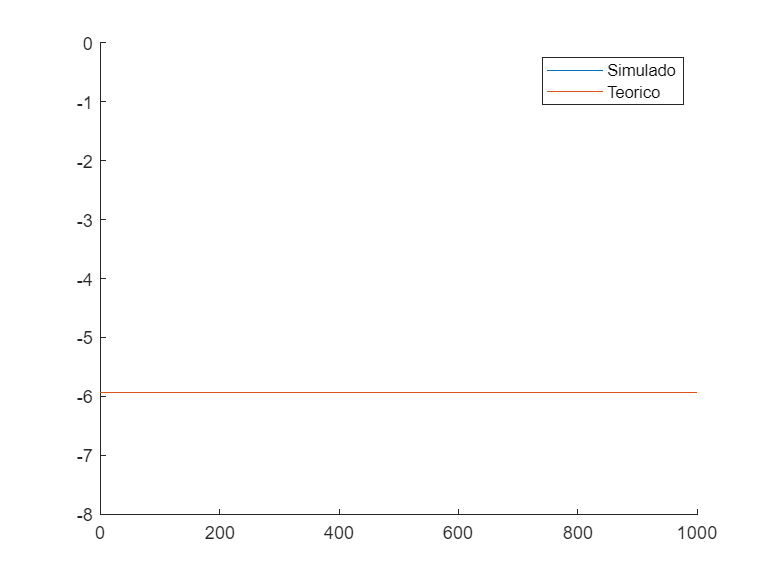

MSE = mean(SE,2);
E_x2 = 10*log10(mean(valorEsperado_x2));
E_erro2 = 10*log10(mean(valorEsperado_erro));

figure()
hold on
plot(10*log10(MSE))
plot([0,1000], [E_erro2, E_erro2])
legend('Simulado', 'Teorico')

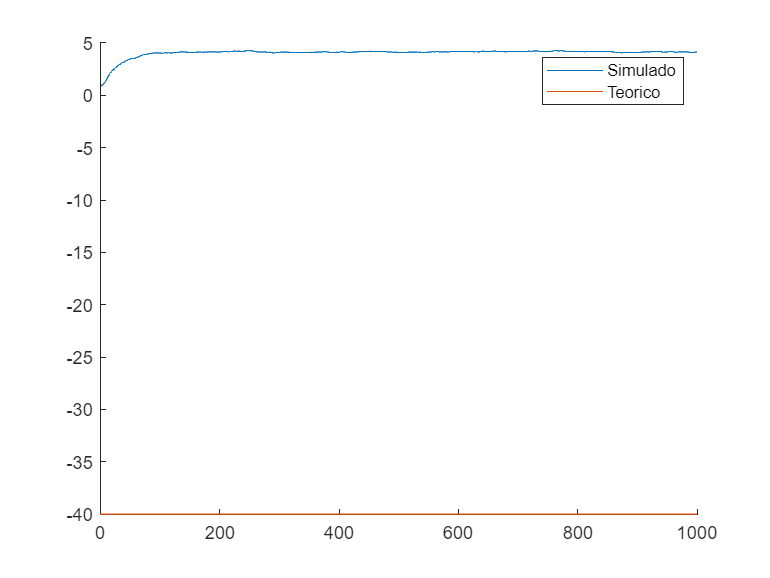

MSD = mean(SD,2);
MSD_teo = 1/2*mu*sigma2v*2*M;
MSD_teo = 10*log10(MSD_teo);

figure()
hold on
plot(10*log10(MSD))
plot([0,1000], [MSD_teo, MSD_teo])
legend('Simulado', 'Teorico')

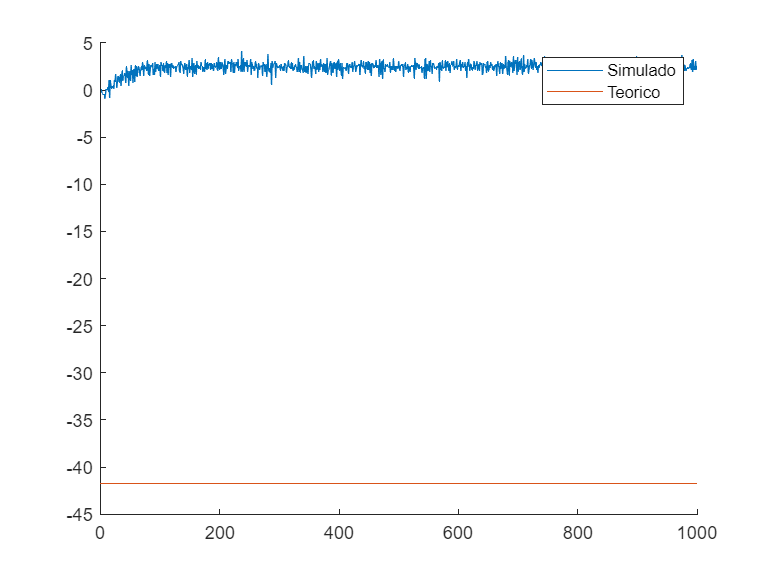

EMSE = mean(ESE,2);
EMSE_teo = 1/2*mu*sigma2v*2*1.334;
EMSE_teo = 10*log10(EMSE_teo);

figure()
hold on
plot(10*log10(EMSE))
plot([0,1000], [EMSE_teo, EMSE_teo])
legend('Simulado', 'Teorico')

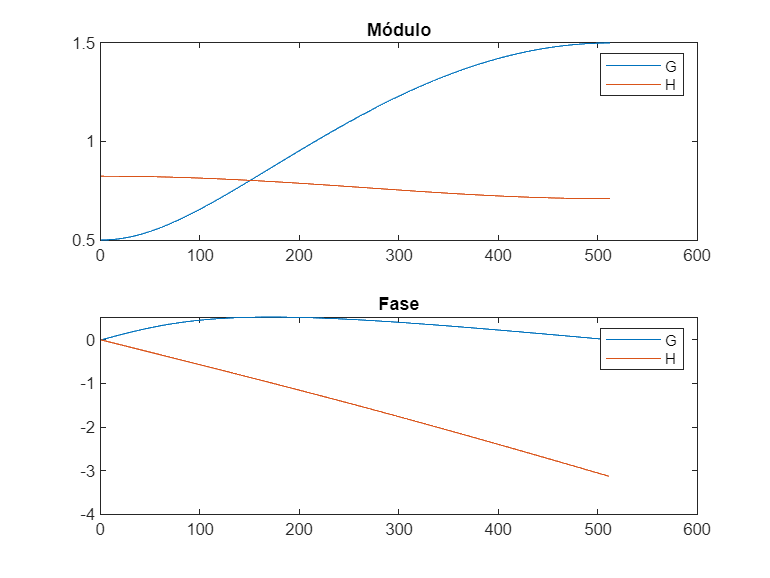

G = freqz(aG,bG);
H = freqz([w(1,end) w(2,end)], 1);
figure()
hold on

subplot(2,1,1);plot(abs(G))
hold on
title('Módulo')
subplot(2,1,1);plot(abs(H))
legend('G', 'H')
subplot(2,1,2);plot(angle(G))
hold on
title('Fase')
subplot(2,1,2);plot(angle(H))
legend('G', 'H')

E_erro_post2 = 10*log10(mean(valorEsperado_erro_post))

E_erro_post2 = 2.4993

Valo

Rphi = [1.334 0.0833;
0.0833 1.334];
r_d_phi = r_dphi(L);
wo = inv(Rphi)*r_dphi(L)

wo =     0.3293
    0.7291


w(:,end)

ans =     0.0571
    0.7667


function r_dphi_ = r_dphi(L)
        r_dphi_ = [0; 0];
        r_dphi_(1) =  0.5^L;
        if L == 0
            r_dphi_(2) = 0;
        else
            r_dphi_(2) = 0.5^(L-1);
        end
end